# Retraining line detector

Retraining the regression model to estimate the target coordinates even for outputs from the camera hardware.

## Initialization

clear; close all; clc; rng('default');

## Labeling

% videoLabeler('trainVideo.avi');

## Speficy ground truth labels

Specify the label files.

fileNames = {'exportedLabels.mat',...
    'exportedLabels2.mat',...
    'exportedLabels3.mat',...
    'exportedLabels4.mat'};
doTraining = false;
doDesignWithDND = false;

## Extract training images from videos

### Load label data

Load label data into the workspace

parentFolder = fullfile(pwd,'dataset');
[~,~] = rmdir(parentFolder,'s');
Y = [];
for k = 1:numel(fileNames)
    d = load(fileNames{k});
    videoName = d.gTruth.DataSource.Source;
    % Create corresponding folders
    [~,filename,~] = fileparts(d.gTruth.DataSource.Source);
    dataFolder = fullfile(parentFolder,filename);
    [~,~,~] = rmdir(dataFolder,'s');
    [~,~,~] = mkdir(dataFolder);
    
    % Extract target coordinates.
    labelData = d.gTruth.LabelData.WhiteLine;
    validVideoIndex = ~cellfun(@isempty,d.gTruth.LabelData.WhiteLine);
    labelData = labelData(validVideoIndex);
    Ytmp = zeros(length(labelData),2);
    for i = 1:length(labelData)
        Ytmp(i,:) = labelData{i}{1}(end,:);
    end
    Y = [Y; Ytmp];
    
    % Extrac the image
    v = VideoReader(videoName);
    wh = [v.Width v.Height];

    videoIndex = find(validVideoIndex);
    for l = 1:numel(videoIndex)
        video = read(v,videoIndex(l));
        imwrite(video,fullfile(dataFolder,num2str(int32(l),'image_%05d.png')));
    end
end

% Visualize
imds = imageDatastore(parentFolder,'IncludeSubfolders',true);
figure;
montage(imds);

When extracting the coordinate values, normalise the coordinates with respect to following settings;

- Defining the centre of the image to be the origin of the Cartesian coordinates system, and

- Defining the coordinates of left side and right side to be ( -1, 1) . 

Y = (Y - wh(1)/2) ./ (wh(1)/2)

## **Splitting dataset into training and test datasets**

rng(0);
shuffledIndices = randperm(imds.numpartitions);
idx = length(shuffledIndices) - 4; % four images for testing
trainImds = imageDatastore(imds.Files(shuffledIndices(1:idx)));
testImds = imageDatastore(imds.Files(shuffledIndices(idx+1:end)));
trainArrayDs = arrayDatastore(Y(shuffledIndices(1:idx),:));
testArrayDs = arrayDatastore(Y(shuffledIndices(idx+1:end),:));

% Combine the image datastore and the target coordinates datastore
trainDs = combine(trainImds,trainArrayDs);
testDs = combine(testImds,testArrayDs);
preview(trainDs)

## **Verifying the extraction of the target coordinates on the image against the original image**

If the target coordinates (red circle) does not coincide with the expected coordinates, check the results of labelling in the previous exercise (specify the topic of mlx-files) .

numPreview = 4;  % selecting first four images

imgData = cell(numPreview,1);
trainDs.reset;
for k = 1:numPreview
    data = read(trainDs);
    pos = data{2} .* (wh(1)/2) + wh(1)/2;
    imgData{k} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
end
figure
montage(imgData, 'BorderSize', 10)

## **Augmentation of training data **

Generating the pseudo data for various scenarios by applying horizontal flip on the original image

augTrainDs = transform(trainDs, @augmentData);

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augTrainDs);
    pos = data{1,2} .* (wh(1)/2) + wh(1)/2;
    augmentedData{k} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
    reset(augTrainDs);
end
figure
montage(augmentedData, 'BorderSize', 10)

## Preparing the network for regression model

if doDesignWithDND
    deepNetworkDesigner
else
    net = resnet18;
    lgraph = layerGraph(net);
    meanVal = lgraph.Layers(1).Mean;
    stddivVal = lgraph.Layers(1).StandardDeviation;
    lgraph = replaceLayer(lgraph,'data',imageInputLayer([wh([2 1]),3],'Name','data',...
        'Normalization','zscore','Mean',meanVal,'StandardDeviation',stddivVal));
    lgraph = replaceLayer(lgraph,'fc1000',fullyConnectedLayer(2,'Name','new_fc'));
    lgraph = removeLayers(lgraph,'prob');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',regressionLayer('Name','regressionoutput'));
    lgraph = connectLayers(lgraph,'new_fc','regressionoutput');
    lgraph_1 = lgraph;
end

## **Setting the options for training **

`MaxEpochs`: Number of training set to be used. If the solution does not converge, incirease the number. 

`InitialLearnRate`: Initial leaning rate. Larger rate tend result in a divergence of the solution. Smaller rate increases the accuracy, however with more computational time. 

`LearnRateDropFactor`: A factor of the learning rate

`LearnRateDropPeriod`: number of epoch to reduce the learning rate 

options = trainingOptions('adam',...
    'MiniBatchSize',32,...
    'MaxEpochs',50,...
    'InitialLearnRate',1e-3,...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',25, ...
    'Shuffle','every-epoch',...
    'ResetInputNormalization',false,...
    'Verbose',true,...
    'Plots','training-progress');

## Training the network

Training progress example:

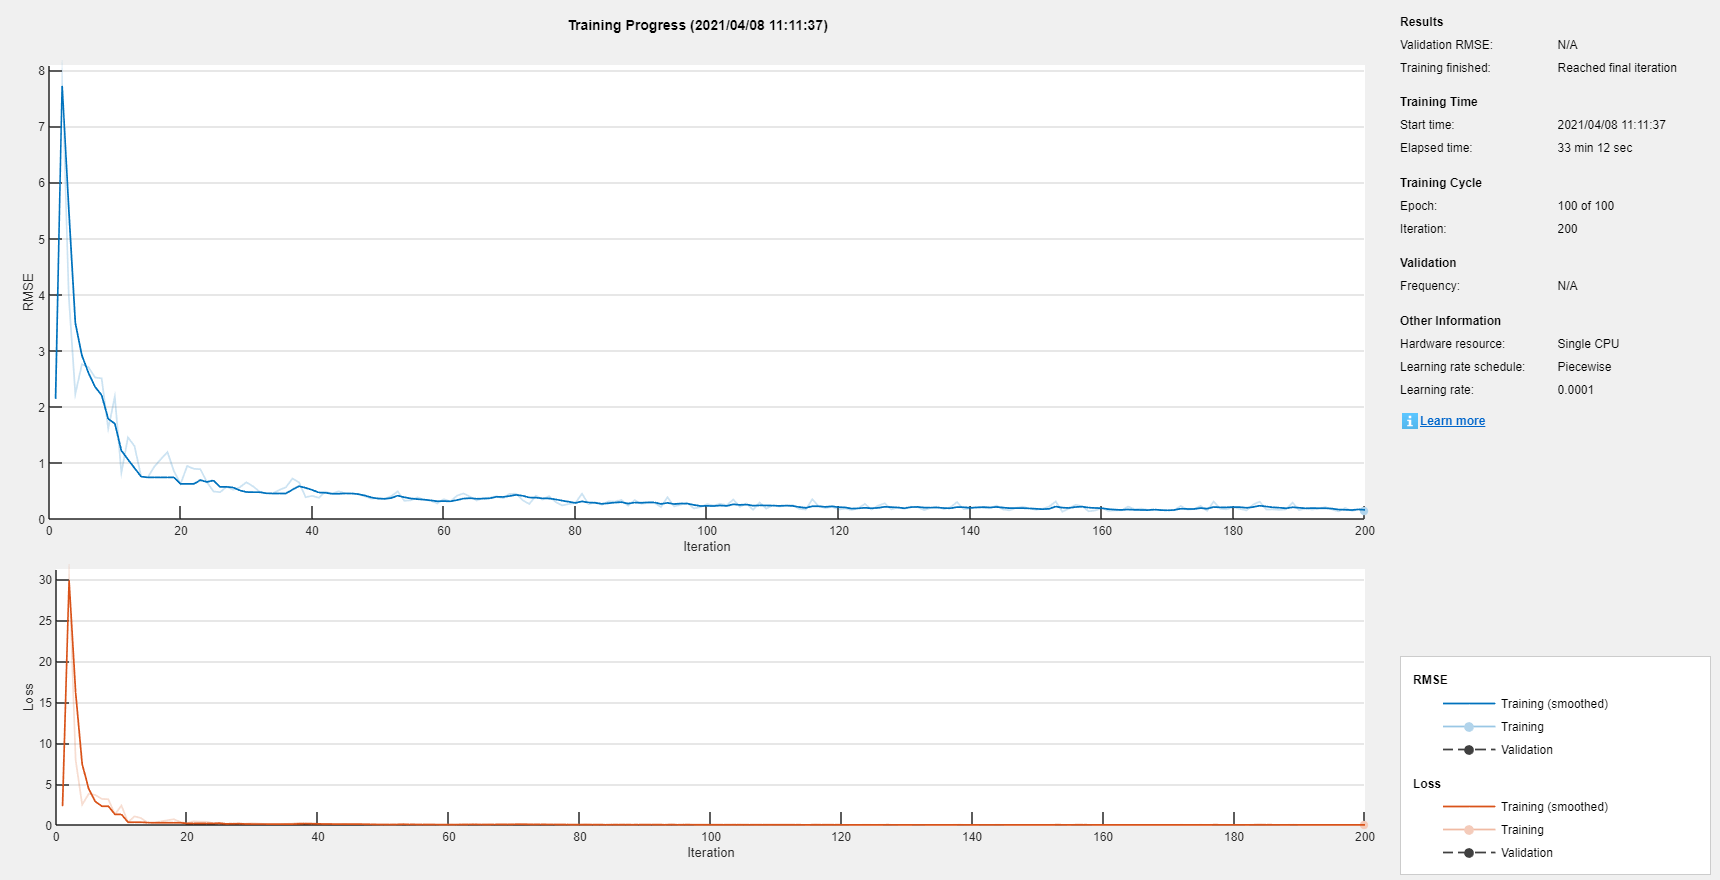

if doTraining
    rng('default');
    trainedNet = trainNetwork(augTrainDs,lgraph_1,options);

    % Save the training results
    save('mynet_new','trainedNet');
else
    load('mynet_new.mat');
end

## **Validation of the trained network.**

testDs.reset;
testData = cell(testDs.numpartitions,1);
for k = 1:testDs.numpartitions
    data = read(testDs);
    imdata = data{1};
    posGt = data{2};
    pos = predict(trainedNet,imdata);
    pos = pos .* (wh(1)/2) + wh(1)/2;
    posGt = posGt .* (wh(1)/2) + wh(1)/2;
    testData{k} = insertShape(imdata, 'FilledCircle', [pos 5],'Color','Red');
    testData{k} = insertShape(testData{k}, 'FilledCircle', [posGt 5],'Color','Green');
end
figure
montage(testData, 'BorderSize', 10)
title('Results (green=ground truth, red=predicted)');

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    pos = A{ii,2};
    sz = size(I);

    if numel(sz) == 3 && sz(3) == 3
        I = jitterColorHSV(I,...
            'Contrast',[0.2 0.8],...
            'Hue',0.05,...
            'Saturation',0.1,...
            'Brightness',0.2);
    end

    % Blur
%     LEN = rand*5;
%     THETA = rand*2*pi;
%     PSF = fspecial('motion', LEN, THETA);
%     I = imfilter(I, PSF, 'conv', 'circular');

    % Randomly flip image.
    tform = randomAffine2d('XReflection',true);
%     ,...
%         'Scale',[0.8 1.2],...
%         'Rotation',[-10 10]);
    rout = affineOutputView(sz,tform,'BoundsStyle','centerOutput');
    I = imwarp(I,tform,'OutputView',rout);

    % Apply same transform to boxes.
    pos = tform.transformPointsForward(pos);

    data(ii,:) = {I, pos};
end
end

*Copyright 2021 The MathWorks, Inc.*